clc; clear;
load("C:\Users\Fabian\Desktop\SoaringCPP\autonomous-soaring\Calculations\Sim_daten\2023-11-23 22-29-21.bin-63665.mat")


res = GPS_0(:,5)/1000

res = 1.0e+05 *

    4.2298
    4.2298
    4.2298
    4.2298
    4.2298
    4.2298
    4.2298
    4.2298
    4.2298
    4.2298


res = res/3600

res =   117.4941
  117.4942
  117.4942
  117.4943
  117.4943
  117.4944
  117.4944
  117.4945
  117.4946
  117.4946


res = mod(res,24)

res =    21.4941
   21.4942
   21.4942
   21.4943
   21.4943
   21.4944
   21.4944
   21.4945
   21.4946
   21.4946




% Initialize an array for the converted times
convertedTimes_Week = res

convertedTimes_Week =    21.4941
   21.4942
   21.4942
   21.4943
   21.4943
   21.4944
   21.4944
   21.4945
   21.4946
   21.4946



% Loop through each value and convert to hours.minutes format
for i = 1:length(res)
    % Extract the integer part (hours)
    hours = floor(res(i));

    % Extract the decimal part (fraction of an hour)
    fractionOfHour = res(i) - hours;

    % Convert the fraction of an hour to minutes and seconds
    minutes = floor(fractionOfHour * 60);
    seconds = (fractionOfHour * 60 - minutes) * 60;

    % Store the result in the new array
    convertedTimes_Week(i) = hours + minutes / 100 + seconds / 10000;
end
convertedTimes_Week = GPS_0(:,5)

convertedTimes_Week =    422978800
   422979000
   422979200
   422979400
   422979600
   422979800
   422980000
   422980200
   422980400
   422980600


convertedTimes = GPS_0(:,2)

convertedTimes =      7876824
     8056388
     8256711
     8456436
     8656810
     8856422
     9056472
     9256981
     9457180
     9657063


% Timestamp US
T = table(convertedTimes,convertedTimes_Week,GPS_0(:,11),GPS_0(:,9),GPS_0(:,10),GPS_0(:,12),GPS_0(:,13), 'VariableNames', {'Timestamp','Timestamp Daytime','ALT','Lat','Long','G-Speed [m/s]','GroundCourse'})

T = 312×7 table
    Timestamp     Timestamp Daytime     ALT       Lat       Long     G-Speed [m/s]    GroundCourse
    __________    _________________    ______    ______    ______    _____________    ____________

    7.8768e+06       4.2298e+08        439.07    46.738    8.1518        0.002           246.65   
    8.0564e+06       4.2298e+08        444.75    47.343    8.2572        0.002            315.2   
    8.2567e+06       4.2298e+08        444.75    47.343    8.2572        0.005           313.83   
    8.4564e+06       4.2298e+08        444.75    47.343    8.2572        0.003           325.98   
    8.6568e+06       4.2298e+08        444.75    47.343    8.2572        0.002           68.755   
    8.8564e+06       4.2298e+08        444.75    47.

% Fixing Alt that it over ground
T.ALT = T.ALT - T.ALT(1);

GyroX =nan(1,length(GPS_0(:,2)));
GyroY =nan(1,length(GPS_0(:,2)));
GyroZ =nan(1,length(GPS_0(:,2)));
AcceX =nan(1,length(GPS_0(:,2)));
AcceY =nan(1,length(GPS_0(:,2)));
AcceZ =nan(1,length(GPS_0(:,2)));


for i = 1:length(GyroX)
    timestampTable = GPS_0(i,2);
    for j = 1:length(IMU_1(:,2))
        if timestampTable == IMU_1(j,2)
            GyroX(i) = IMU_1(j,4);
            GyroY(i) = IMU_1(j,5);
            GyroZ(i) = IMU_1(j,6);
            AcceX(i) = IMU_1(j,7);
            AcceY(i) = IMU_1(j,8);
            AcceZ(i) = IMU_1(j,9);
        end
    end
end
GyroX

GyroX =     0.0019    0.0017    0.0036    0.0028    0.0024    0.0036    0.0017    0.0035    0.0029    0.0019    0.0014    0.0021    0.0011    0.0017    0.0015    0.0015    0.0013    0.0015    0.0015    0.0018    0.0014    0.0009    0.0019    0.0014    0.0008    0.0010    0.0019    0.0014    0.0012    0.0023    0.0017    0.0020    0.0013    0.0014    0.0014    0.0022    0.0017    0.0015    0.0018    0.0014    0.0025    0.0013    0.0015    0.0017    0.0010    0.0025    0.0014    0.0023    0.0013    0.0008


countNonNaN = sum(~isnan(GyroX));
countNonNaN

countNonNaN = 312


T.GyroX = GyroX';
T.GyroY = GyroY';
T.GyroZ = GyroZ';
T.AcceX = AcceX';
T.AcceY = AcceY';
T.AcceZ = AcceZ'

T = 312×13 table
    Timestamp     Timestamp Daytime    ALT      Lat       Long     G-Speed [m/s]    GroundCourse      GyroX         GyroY          GyroZ        AcceX      AcceY       AcceZ 
    __________    _________________    ____    ______    ______    _____________    ____________    _________    ___________    ___________    _______    ________    _______

    7.8768e+06       4.2298e+08           0    46.738    8.1518        0.002           246.65       0.0018669    -0.00030852     0.00047069    0.68791     -1.1793    -9.7906
    8.0564e+06    

%Airspeed
% Initialize an array to store the indices
closestIndices = zeros(size(GPS_0, 1), 1);

% Loop over each timestamp in the first vector
for i = 1:size(GPS_0, 1)
    % Find the index in the second vector with the closest timestamp
    [~, index] = min(abs(ARSP_0(:,2) - GPS_0(i,2)));
    % Store the index in the array
    closestIndices(i) = index;
end

% Now, closestIndices contains the indices in the second vector corresponding to the closest timestamps in the first vector
closestIndices

closestIndices =     52
    53
    55
    57
    59
    61
    63
    65
    67
    69




Airspeed = ARSP_0(closestIndices,4)

Airspeed =     0.0221
    0.0221
    0.0221
    0.0221
    0.0221
    0.0221
    0.0221
    0.0221
    0.0221
    0.0221



T.Airspeed = Airspeed

T = 312×14 table
    Timestamp     Timestamp Daytime    ALT      Lat       Long     G-Speed [m/s]    GroundCourse      GyroX         GyroY          GyroZ        AcceX      AcceY       AcceZ     Airspeed
    __________    _________________    ____    ______    ______    _____________    ____________    _________    ___________    ___________    _______    ________    _______    ________

    7.8768e+06       4.2298e+08           0    46.738    8.1518        0.002           246.65       0.0018669    -0.00030852     0.000

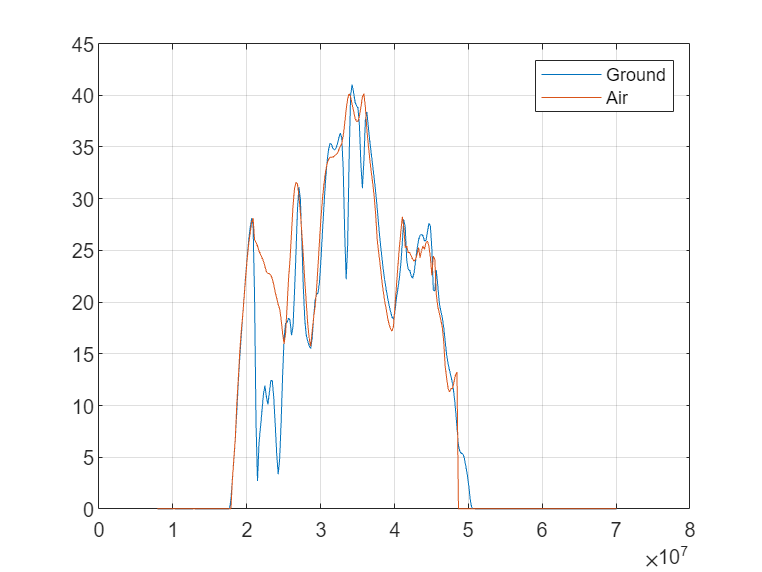



plot(T.Timestamp,T.("G-Speed [m/s]"),T.Timestamp,T.Airspeed)
hold on
grid on
legend('Ground','Air')
hold off

%Baro and Temp
% Initialize an array to store the indices
closestIndices = zeros(size(GPS_0, 1), 1);

% Loop over each timestamp in the first vector
for i = 1:size(GPS_0, 1)
    % Find the index in the second vector with the closest timestamp
    [~, index] = min(abs(BARO_0(:,2) - GPS_0(i,2)));
    % Store the index in the array
    closestIndices(i) = index;
end

% Now, closestIndices contains the indices in the second vector corresponding to the closest timestamps in the first vector
closestIndices

closestIndices =     52
    53
    55
    57
    59
    61
    63
    65
    67
    69




Barometer = BARO_0(closestIndices,5)

Barometer = 1.0e+04 *

    9.6096
    9.6096
    9.6094
    9.6096
    9.6097
    9.6095
    9.6094
    9.6097
    9.6095
    9.6094


T.Barometer = Barometer

T = 312×15 table
    Timestamp     Timestamp Daytime    ALT      Lat       Long     G-Speed [m/s]    GroundCourse      GyroX         GyroY          GyroZ        AcceX      AcceY       AcceZ     Airspeed    Barometer
    __________    _________________    ____    ______    ______    _____________    ____________    _________    ___________    ___________    _______    ________    _______    ________    _________

    7.8768e+06       4.2298e+08           0    46.738    8.1518        0.0

Temperature = BARO_0(closestIndices,6)

Temperature =    26.6500
   26.6700
   26.7000
   26.7400
   26.7700
   26.8100
   26.8500
   26.8800
   26.9100
   26.9500


T.Temperature = Temperature

T = 312×16 table
    Timestamp     Timestamp Daytime    ALT      Lat       Long     G-Speed [m/s]    GroundCourse      GyroX         GyroY          GyroZ        AcceX      AcceY       AcceZ     Airspeed    Barometer    Temperature
    __________    _________________    ____    ______    ______    _____________    ____________    _________    ___________    ___________    _______    ________    _______    ________    _________    ___________

    7.8768

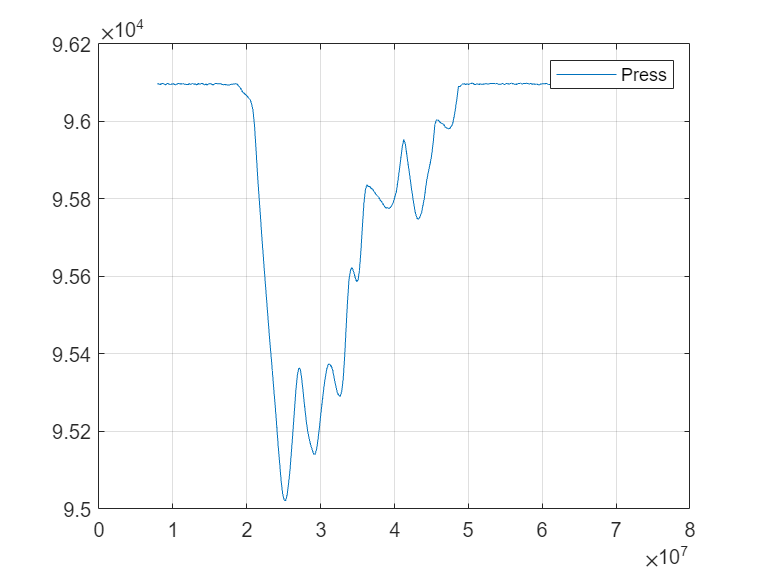


plot(T.Timestamp,T.Barometer)
hold on
grid on
legend('Press')
hold off

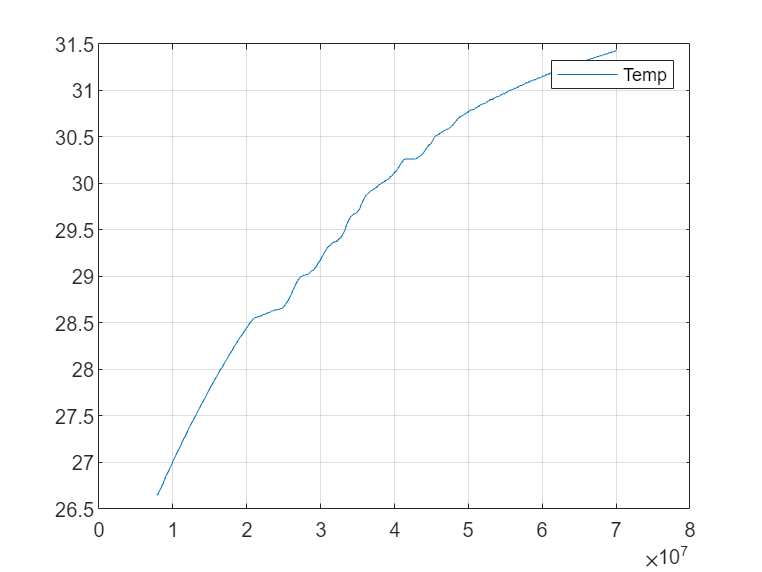


plot(T.Timestamp,T.Temperature)
hold on
grid on
legend('Temp')
hold off

% Energie
Energie =nan(1,length(GPS_0(:,2)));
g= 9.81

g = 9.8100


for i = 1:size(GPS_0, 1)
    Energie(i) = 1./(2*g)*(T.Airspeed(i))^2+T.ALT(i);
end

Energie

Energie =     0.0000    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800    5.6800



% Ableitung
EnergieAb =nan(1,length(GPS_0(:,2)));
for i = 2:(length(Energie))
    EnergieAb(i) = Energie(i)-Energie(i-1);
end

EnergieAb

EnergieAb =        NaN    5.6800         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0



T.Energie = Energie';
T.EnergieAbleitung = EnergieAb'

T = 312×18 table
    Timestamp     Timestamp Daytime    ALT      Lat       Long     G-Speed [m/s]    GroundCourse      GyroX         GyroY          GyroZ        AcceX      AcceY       AcceZ     Airspeed    Barometer    Temperature     Energie      EnergieAbleitung
    __________    _________________    ____    ______    ______    _____________    ____________    _________    ___________    ___________    _______    ________    _______    ________    <s

%Heading Roll Pitch Yaw
% Initialize an array to store the indices
closestIndices = zeros(size(GPS_0, 1), 1);

% Loop over each timestamp in the first vector
for i = 1:size(GPS_0, 1)
    % Find the index in the second vector with the closest timestamp
    [~, index] = min(abs(ATT(:,2) - GPS_0(i,2)));
    % Store the index in the array
    closestIndices(i) = index;
end

% Now, closestIndices contains the indices in the second vector corresponding to the closest timestamps in the first vector
closestIndices

closestIndices =    128
   132
   138
   142
   148
   152
   157
   163
   168
   173



% Convert into RADIANS and save in Table
ROLL = ATT(closestIndices,4)

ROLL =     6.9500
    6.9500
    6.9500
    6.9500
    6.9500
    6.9500
    6.9500
    6.9500
    6.9500
    6.9500


ROLL = deg2rad(ROLL)

ROLL =     0.1213
    0.1213
    0.1213
    0.1213
    0.1213
    0.1213
    0.1213
    0.1213
    0.1213
    0.1213


T.Roll = ROLL

T = 312×19 table
    Timestamp     Timestamp Daytime    ALT      Lat       Long     G-Speed [m/s]    GroundCourse      GyroX         GyroY          GyroZ        AcceX      AcceY       AcceZ     Airspeed    Barometer    Temperature     Energie      EnergieAbleitung     Roll 
    __________    _________________    ____    ______    ______    _____________    ____________    _________    ___________    ___________    _______    ________    _______    


PITCH = ATT(closestIndices,6)

PITCH =     4.9400
    4.9500
    4.9400
    4.9400
    4.9400
    4.9400
    4.9500
    4.9300
    4.9400
    4.9400


PITCH = deg2rad(PITCH)

PITCH =     0.0862
    0.0864
    0.0862
    0.0862
    0.0862
    0.0862
    0.0864
    0.0860
    0.0862
    0.0862


T.Pitch = PITCH

T = 312×20 table
    Timestamp     Timestamp Daytime    ALT      Lat       Long     G-Speed [m/s]    GroundCourse      GyroX         GyroY          GyroZ        AcceX      AcceY       AcceZ     Airspeed    Barometer    Temperature     Energie      EnergieAbleitung     Roll      Pitch  
    __________    _________________    ____    ______    ______    _____________    ____________    _________    ___________    ___________    _______    ________    


YAW = ATT(closestIndices,8)

YAW =    47.1800
   47.1800
   47.1900
   47.1900
   47.1900
   47.1800
   47.1900
   47.1900
   47.1900
   47.1900


YAW = deg2rad(YAW)

YAW =     0.8234
    0.8234
    0.8236
    0.8236
    0.8236
    0.8234
    0.8236
    0.8236
    0.8236
    0.8236


T.Yaw = YAW

T = 312×21 table
    Timestamp     Timestamp Daytime    ALT      Lat       Long     G-Speed [m/s]    GroundCourse      GyroX         GyroY          GyroZ        AcceX      AcceY       AcceZ     Airspeed    Barometer    Temperature     Energie      EnergieAbleitung     Roll      Pitch        Yaw  
    __________    _________________    ____    ______    ______    _____________    ____________    _________    ___________    ___________    _______    

%Humidity
T.Humidity = repmat(20, height(T), 1)

T = 312×22 table
    Timestamp     Timestamp Daytime    ALT      Lat       Long     G-Speed [m/s]    GroundCourse      GyroX         GyroY          GyroZ        AcceX      AcceY       AcceZ     Airspeed    Barometer    Temperature     Energie      EnergieAbleitung     Roll      Pitch        Yaw      Humidity
    __________    _________________    ____    ______    ______    _____________    ____________    _________    ___________    ___________    

FontSize = 30;
LineWidth = 100;
gx = geoscatter(T.Lat(2:end),T.Long(2:end),LineWidth)

gx =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
          LineWidth: 0.5000
       LatitudeData: [47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 … ]
      LongitudeData: [8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 … ]
              ZData: [1×0 double]
           SizeData: 100
              CData: [0 0.4470 0.7410]

  Show 

hold on;
lgd=legend("Flightpath",'Location','northwest')

lgd =   Legend (Flightpath) with properties:

         String: {'Flightpath'}
       Location: 'northwest'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.1762 0.8579 0.1875 0.0429]
          Units: 'normalized'

  Show all properties


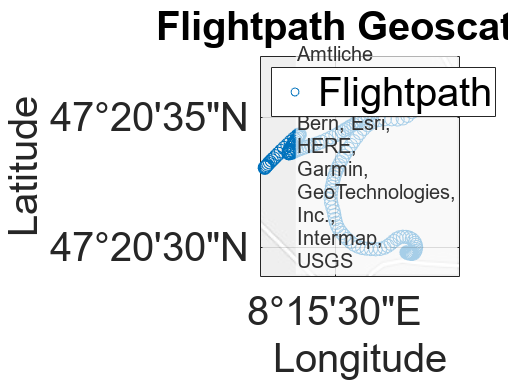

title("Flightpath Geoscatter")
fontsize(lgd,FontSize,'points');
fontsize(gca, FontSize,'points');
hold off;

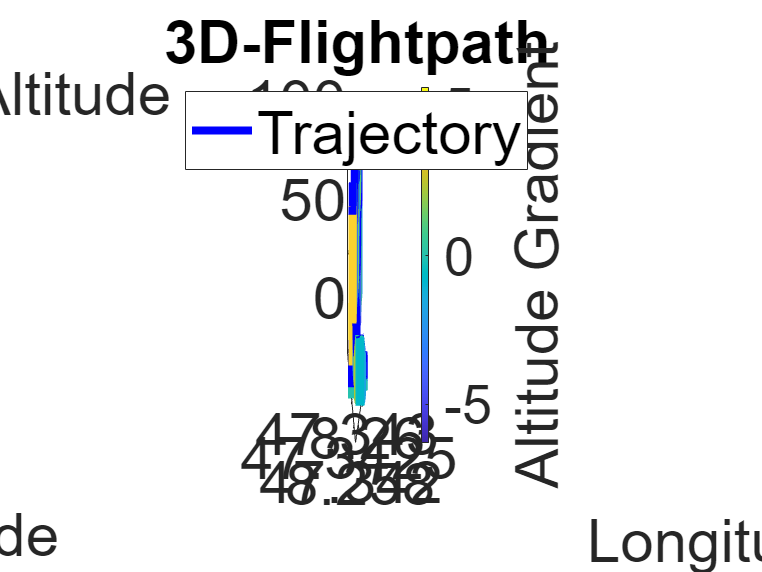

LineWidth = 4;
FontSize = 30;
% Plot the 3D trajectory
plot3(T.Long(2:end), T.Lat(2:end), T.ALT(2:end), 'b-', 'LineWidth', LineWidth);
hold on;

% Initialize gradient vector
gradient = zeros(size(T.ALT));

% Calculate gradient for each data point
for i = 2:length(T.ALT)
    altdiff = T.ALT(i) - T.ALT(i-1);
    gradient(i) = altdiff;
end

% Map gradient to colors
cd = colormap('parula');
cd = interp1(linspace(min(gradient), max(gradient), length(cd)), cd, gradient);
cd = uint8(cd' * 255);
cd(4, :) = 255;

% Plot lines from ground to each data point with different colors based on gradient
for i = 2:length(T.Long)
    % Select color for this line
    color = cd(:, i);
    
    % Plot the line with the determined color
    plot3([T.Long(i) T.Long(i)], [T.Lat(i) T.Lat(i)], [0 T.ALT(i)], 'Color', color, 'LineWidth', LineWidth);
end

% Create a colorbar
c = colorbar;
c.Label.String = 'Altitude Gradient';
caxis([min(gradient), max(gradient)]);
title("3D-Flightpath")
xlabel('Longitude');
ylabel("Latitude");
zlabel("Altitude");
% Create legend
lgd=legend('Trajectory', 'Location', 'Best');
fontsize(lgd,FontSize,'points');
fontsize(gca, FontSize,'points');

hold off;

% Create SAVE Tasble with correct data sequence
SaveTable = table(T.Timestamp,T.("Timestamp Daytime"),T.Humidity,T.("G-Speed [m/s]"),T.Airspeed,T.Temperature,T.Barometer,T.Long,T.Lat,T.ALT,T.Roll,T.Pitch,T.Yaw,T.Energie,T.EnergieAbleitung,T.GyroX,T.GyroY,T.GyroZ,T.AcceX,T.AcceY,T.AcceZ,'VariableNames', {'Time since System Start [us]','Time Day','Humidity [%]','Groundspeed [m/s]','Airspeed [m/s]','Temperature [deg C]','Airpressure [kPas]','Longitude','Latitude','Flight Height [m]','Roll [deg]','Pitch [deg]','Yaw [deg]','Energie [m]','Energieableitung [m/s]','GyroX','GyroY','GyroZ','AcceX','AcceY','AcceZ'})

SaveTable = 312×21 table
    Time since System Start [us]     Time Day     Humidity [%]    Groundspeed [m/s]    Airspeed [m/s]    Temperature [deg C]    Airpressure [kPas]    Longitude    Latitude    Flight Height [m]    Roll [deg]    Pitch [deg]    Yaw [deg]    Energie [m]    Energieableitung [m/s]      GyroX         GyroY          GyroZ        AcceX      AcceY       AcceZ 
    ____________________________    __________    ____________    _________________    ______________    ___________________    __________________

writetable(SaveTable,'ShortFlight.csv','Delimiter',';')    

timediff(1) =0 ;
for i= 2:length(T.Timestamp)

   timediff(i-1) = T.Timestamp(i)-T.Timestamp(i-1);


end

i = 1:length(timediff)

i =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


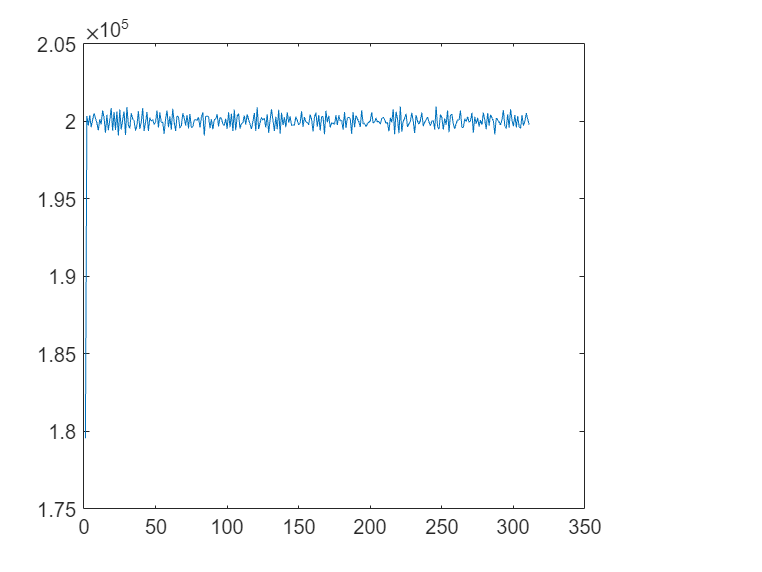

plot(i,timediff)


timediff(1) =0 ;
for i= 2:length(T.("Timestamp Daytime"))

   timediffDay(i-1) = T.("Timestamp Daytime")(i)-T.("Timestamp Daytime")(i-1);


end

i = 1:length(timediffDay)

i =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


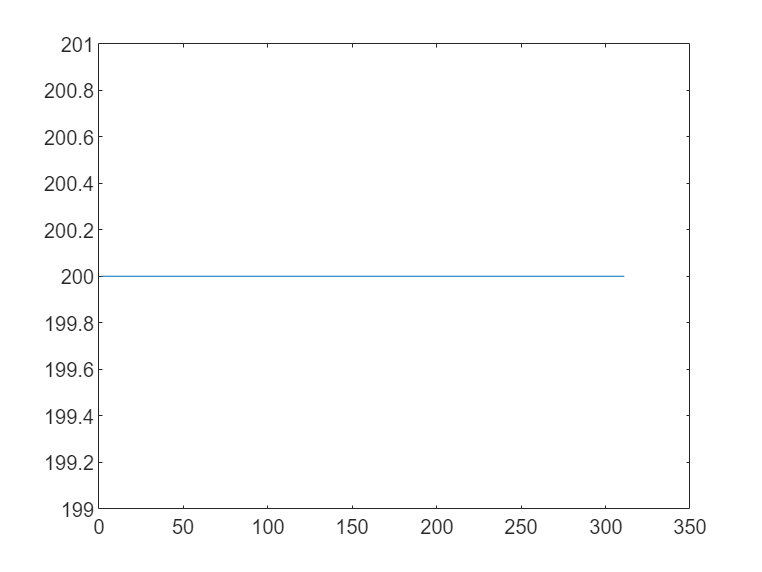

plot(i,timediffDay)